% Data Analysis - Bending-Torsion Lab - Group 18
% ====================================================
clear; clc

path = "Actual_lab_data.xlsx"

path = "Actual_lab_data.xlsx"


%data_all = readtable("Actual_lab_data.xlsx","VariableNamingRule","preserve");
data_all = readtable(path,"VariableNamingRule","preserve");

cde_ex = 'r'

cde_ex = 'r'

fgh_ex = 'b'

fgh_ex = 'b'

ijk_ex = 'g'

ijk_ex = 'g'


line_w = 1.5

line_w = 1.5000

load_s = '-'

load_s = '-'

unload_s = '--'

unload_s = '--'



theo_re = 'y'

theo_re = 'y'

theo_sim = 'c'

theo_sim = 'c'

fea_re = 'm'

fea_re = 'm'


% Parameters
%-------------------------------------------------------------------
% If data is in output Voltage, convert to strain
Vin = 15;         % input voltage (V)
Sgauge = 2.09;    % strain gauge factor
Gamp = 1000;      % amplified amplitude voltage
unit_out = 10e-6; % microVoltage
convert_to_strain = 4*unit_out/(Vin*Sgauge*Gamp); % Conversion factor from voltage to strain
convert_to_strain = 1e-6; % use this if no conversion is required 

thickness = [0.64 1.7 2.34 0.64 2.23 1.59] .* 1e-3; % thicknesses of walls
G = 28e9; % Shear Modulus


% Experiment parameters
targetLoad = [0,10,20,30,40,50,40,30,20,10,0]; % Target load increments for experiment
loading_idx = 1:1:6;
unloading_idx = 6:1:11;
unloading_idx = 6:1:11;
theta_gauge = [-45,0,45]; % angles of strain gauges 

% Extract readigns
% -------------------------------------------------------------------
% Front Spar
exp_data.FS.actualLoad  = table2array(data_all(1:11,1)); % Load readigns
exp_data.FS.actual = convert_to_strain * table2array(data_all(1:11,2:10)); % Actual readings
exp_data.FS.upper = convert_to_strain * table2array(data_all(1:11,13:21)); % Upper readings
exp_data.FS.lower = convert_to_strain * table2array(data_all(1:11,24:32)); % Lower readigns
exp_data.FS.mean = (exp_data.FS.upper + exp_data.FS.lower)/2;              % Mean readings
exp_data.FS.uncertainty = (exp_data.FS.upper - exp_data.FS.lower);         % Uncertainty

exp_data.FS.ABL_actual = convert_to_strain * table2array(data_all(30:40,2:4));  % Actual readings
exp_data.FS.ABL_upper = convert_to_strain * table2array(data_all(30:40,6:9));   % Upper readings
exp_data.FS.ABL_lower = convert_to_strain * table2array(data_all(30:40,11:14)); % Lower readigns
exp_data.FS.ABL_mean = (exp_data.FS.ABL_upper + exp_data.FS.ABL_lower)/2;       % Mean readings
exp_data.FS.ABL_uncertainty = (exp_data.FS.ABL_upper - exp_data.FS.ABL_lower);  % Uncertainty

% Rear Spar
exp_data.RS.actualLoad  = table2array(data_all(15:25,1));
exp_data.RS.actual = convert_to_strain * table2array(data_all(15:25,2:10));
exp_data.RS.upper = convert_to_strain * table2array(data_all(15:25,13:21));
exp_data.RS.lower = convert_to_strain * table2array(data_all(15:25,24:32));
exp_data.RS.mean = (exp_data.RS.upper + exp_data.RS.lower)/2;
exp_data.RS.uncertainty = (exp_data.RS.upper - exp_data.RS.lower);

exp_data.FS.ABL_actual = convert_to_strain * table2array(data_all(44:54,2:4));
exp_data.FS.ABL_upper = convert_to_strain * table2array(data_all(44:54,6:9));
exp_data.FS.ABL_lower = convert_to_strain * table2array(data_all(44:54,11:14));
exp_data.FS.ABL_mean = (exp_data.FS.ABL_upper + exp_data.FS.ABL_lower)/2;
exp_data.FS.ABL_uncertainty = (exp_data.FS.ABL_upper - exp_data.FS.ABL_lower);

% Calculate strain compoenents
%-----------------------------------------------------------------
[exp_data.FS.epsilon_x_CDE,exp_data.FS.epsilon_y_CDE,exp_data.FS.gamma_xy_CDE] = shearCalc(exp_data.FS.actual(:,1:3),theta_gauge);
[exp_data.FS.epsilon_x_FGH,exp_data.FS.epsilon_y_FGH,exp_data.FS.gamma_xy_FGH] = shearCalc(exp_data.FS.actual(:,4:6),theta_gauge);
[exp_data.FS.epsilon_x_IJK,exp_data.FS.epsilon_y_IJK,exp_data.FS.gamma_xy_IJK] = shearCalc(exp_data.FS.actual(:,7:9),theta_gauge);

[exp_data.RS.epsilon_x_CDE,exp_data.RS.epsilon_y_CDE,exp_data.RS.gamma_xy_CDE] = shearCalc(exp_data.RS.actual(:,1:3),theta_gauge);
[exp_data.RS.epsilon_x_FGH,exp_data.RS.epsilon_y_FGH,exp_data.RS.gamma_xy_FGH] = shearCalc(exp_data.RS.actual(:,4:6),theta_gauge);
[exp_data.RS.epsilon_x_IJK,exp_data.RS.epsilon_y_IJK,exp_data.RS.gamma_xy_IJK] = shearCalc(exp_data.RS.actual(:,7:9),theta_gauge);

% Calculate errors
% ----------------------------------------------------------------
% Front spar maximum values
[exp_data.FS.max_epsilon_x_CDE,exp_data.FS.max_epsilon_y_CDE,exp_data.FS.max_gamma_xy_CDE] = shearCalc(exp_data.FS.upper(:,1:3),theta_gauge);
[exp_data.FS.max_epsilon_x_FGH,exp_data.FS.max_epsilon_y_FGH,exp_data.FS.max_gamma_xy_FGH] = shearCalc(exp_data.FS.upper(:,4:6),theta_gauge);
[exp_data.FS.max_epsilon_x_IJK,exp_data.FS.max_epsilon_y_IJK,exp_data.FS.max_gamma_xy_IJK] = shearCalc(exp_data.FS.upper(:,7:9),theta_gauge);

% Rear spar maximum values
[exp_data.RS.min_epsilon_x_CDE,exp_data.RS.min_epsilon_y_CDE,exp_data.RS.max_gamma_xy_CDE] = shearCalc(exp_data.RS.upper(:,1:3),theta_gauge);
[exp_data.RS.min_epsilon_x_FGH,exp_data.RS.min_epsilon_y_FGH,exp_data.RS.max_gamma_xy_FGH] = shearCalc(exp_data.RS.upper(:,4:6),theta_gauge);
[exp_data.RS.min_epsilon_x_IJK,exp_data.RS.min_epsilon_y_IJK,exp_data.RS.max_gamma_xy_IJK] = shearCalc(exp_data.RS.upper(:,7:9),theta_gauge);

% Front spar minimum values
[exp_data.FS.max_epsilon_x_CDE,exp_data.FS.max_epsilon_y_CDE,exp_data.FS.min_gamma_xy_CDE] = shearCalc(exp_data.FS.lower(:,1:3),theta_gauge);
[exp_data.FS.max_epsilon_x_FGH,exp_data.FS.max_epsilon_y_FGH,exp_data.FS.min_gamma_xy_FGH] = shearCalc(exp_data.FS.lower(:,4:6),theta_gauge);
[exp_data.FS.max_epsilon_x_IJK,exp_data.FS.max_epsilon_y_IJK,exp_data.FS.min_gamma_xy_IJK] = shearCalc(exp_data.FS.lower(:,7:9),theta_gauge);

% Rear spar minimum values
[exp_data.RS.min_epsilon_x_CDE,exp_data.RS.min_epsilon_y_CDE,exp_data.RS.min_gamma_xy_CDE] = shearCalc(exp_data.RS.lower(:,1:3),theta_gauge);
[exp_data.RS.min_epsilon_x_FGH,exp_data.RS.min_epsilon_y_FGH,exp_data.RS.min_gamma_xy_FGH] = shearCalc(exp_data.RS.lower(:,4:6),theta_gauge);
[exp_data.RS.min_epsilon_x_IJK,exp_data.RS.min_epsilon_y_IJK,exp_data.RS.min_gamma_xy_IJK] = shearCalc(exp_data.RS.lower(:,7:9),theta_gauge);

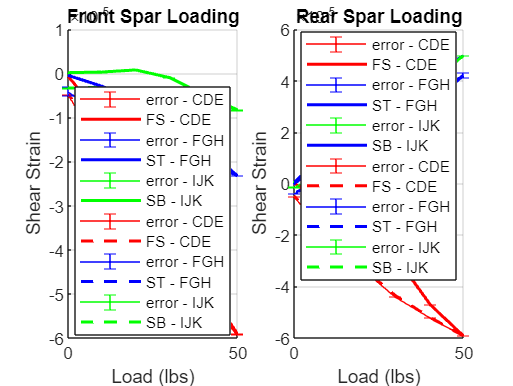

% % Plot shear strain vs load
% figure; hold on
% plot(exp_data.FS.actualLoad,exp_data.FS.gamma_xy_CDE, DisplayName='FS - CDE')
% plot(exp_data.FS.actualLoad,exp_data.FS.gamma_xy_FGH, DisplayName='FS - FGH')
% plot(exp_data.FS.actualLoad,exp_data.FS.gamma_xy_IJK, DisplayName='FS - IJK')
% plot(exp_data.FS.actualLoad,exp_data.RS.gamma_xy_CDE, DisplayName='RS - CDE')
% plot(exp_data.FS.actualLoad,exp_data.RS.gamma_xy_FGH, DisplayName='RS - FGH')
% plot(exp_data.FS.actualLoad,exp_data.RS.gamma_xy_IJK, DisplayName='RS - IJK')
% grid on; 
% legend
% xlabel('Load (lbs)'); ylabel('Shear Strain')
% xlim([0,50])
% hold off


figure
% Plot Shear Strain vs load with errorbars for Front Spar
subplot(1,2,1); hold on
% loading
% FS - CDE
errorbar(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_CDE(loading_idx),[exp_data.FS.min_gamma_xy_CDE(loading_idx) - exp_data.FS.gamma_xy_CDE(loading_idx)],[exp_data.FS.max_gamma_xy_CDE(loading_idx) - exp_data.FS.gamma_xy_CDE(loading_idx)], Color = cde_ex, DisplayName='error - CDE')
plot(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_CDE(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = cde_ex, DisplayName='FS - CDE')
% FS - FGH
errorbar(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_FGH(loading_idx),[exp_data.FS.min_gamma_xy_FGH(loading_idx) - exp_data.FS.gamma_xy_FGH(loading_idx)],[exp_data.FS.max_gamma_xy_FGH(loading_idx) - exp_data.FS.gamma_xy_FGH(loading_idx)], Color = fgh_ex, DisplayName='error - FGH')
plot(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_FGH(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = fgh_ex, DisplayName='ST - FGH')
% FS - IJK
errorbar(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_IJK(loading_idx),[exp_data.FS.min_gamma_xy_IJK(loading_idx) - exp_data.FS.gamma_xy_IJK(loading_idx)],[exp_data.FS.max_gamma_xy_IJK(loading_idx) - exp_data.FS.gamma_xy_IJK(loading_idx)], Color = ijk_ex, DisplayName='error - IJK')
plot(exp_data.FS.actualLoad(loading_idx),exp_data.FS.gamma_xy_IJK(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = ijk_ex, DisplayName='SB - IJK')

% legend('AutoUpdate','off')
legend('Location','best')


% unloading
% FS - CDE
errorbar(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_CDE(unloading_idx),[exp_data.FS.min_gamma_xy_CDE(unloading_idx) - exp_data.FS.gamma_xy_CDE(unloading_idx)],[exp_data.FS.max_gamma_xy_CDE(unloading_idx) - exp_data.FS.gamma_xy_CDE(unloading_idx)], Color = cde_ex, DisplayName='error - CDE')
plot(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_CDE(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = cde_ex, DisplayName='FS - CDE')
% FS - FGH
errorbar(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_FGH(unloading_idx),[exp_data.FS.min_gamma_xy_FGH(unloading_idx) - exp_data.FS.gamma_xy_FGH(unloading_idx)],[exp_data.FS.max_gamma_xy_FGH(unloading_idx) - exp_data.FS.gamma_xy_FGH(unloading_idx)], Color = fgh_ex, DisplayName='error - FGH')
plot(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_FGH(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = fgh_ex, DisplayName='ST - FGH')
% FS - IJK
errorbar(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_IJK(unloading_idx),[exp_data.FS.min_gamma_xy_IJK(unloading_idx) - exp_data.FS.gamma_xy_IJK(unloading_idx)],[exp_data.FS.max_gamma_xy_IJK(unloading_idx) - exp_data.FS.gamma_xy_IJK(unloading_idx)], Color = ijk_ex, DisplayName='error - IJK')
plot(exp_data.FS.actualLoad(unloading_idx),exp_data.FS.gamma_xy_IJK(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = ijk_ex, DisplayName='SB - IJK')

legend
grid
xlabel('Load (lbs)'); ylabel('Shear Strain')
title('Front Spar Loading')
xlim([0,50])
hold off

% Plot Shear Strain vs load with errorbars for Front Spar
subplot(1,2,2); hold on

% RS - CDE
errorbar(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_CDE(loading_idx),[exp_data.RS.min_gamma_xy_CDE(loading_idx) - exp_data.RS.gamma_xy_CDE(loading_idx)],[exp_data.RS.max_gamma_xy_CDE(loading_idx) - exp_data.RS.gamma_xy_CDE(loading_idx)], Color = cde_ex, DisplayName='error - CDE')
plot(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_CDE(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = cde_ex, DisplayName='FS - CDE')
% RS - FGH
errorbar(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_FGH(loading_idx),[exp_data.RS.min_gamma_xy_FGH(loading_idx) - exp_data.RS.gamma_xy_FGH(loading_idx)],[exp_data.RS.max_gamma_xy_FGH(loading_idx) - exp_data.RS.gamma_xy_FGH(loading_idx)], Color = fgh_ex, DisplayName='error - FGH')
plot(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_FGH(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = fgh_ex, DisplayName='ST - FGH')
% RS - IJK
errorbar(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_IJK(loading_idx),[exp_data.RS.min_gamma_xy_IJK(loading_idx) - exp_data.RS.gamma_xy_IJK(loading_idx)],[exp_data.RS.max_gamma_xy_IJK(loading_idx) - exp_data.RS.gamma_xy_IJK(loading_idx)], Color = ijk_ex, DisplayName='error - IJK')
plot(exp_data.RS.actualLoad(loading_idx),exp_data.RS.gamma_xy_IJK(loading_idx),LineWidth = line_w, LineStyle = load_s, Color = fgh_ex, DisplayName='SB - IJK')
% legend('AutoUpdate','off')

% unloading
% RS - CDE
errorbar(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_CDE(unloading_idx),[exp_data.RS.min_gamma_xy_CDE(unloading_idx) - exp_data.RS.gamma_xy_CDE(unloading_idx)],[exp_data.RS.max_gamma_xy_CDE(unloading_idx) - exp_data.RS.gamma_xy_CDE(unloading_idx)], Color = cde_ex, DisplayName='error - CDE')
plot(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_CDE(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = cde_ex, DisplayName='FS - CDE')
% RS - FGH
errorbar(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_FGH(unloading_idx),[exp_data.RS.min_gamma_xy_FGH(unloading_idx) - exp_data.RS.gamma_xy_FGH(unloading_idx)],[exp_data.RS.max_gamma_xy_FGH(unloading_idx) - exp_data.RS.gamma_xy_FGH(unloading_idx)], Color = fgh_ex, DisplayName='error - FGH')
plot(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_FGH(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = fgh_ex, DisplayName='ST - FGH')
% RS - IJK
errorbar(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_IJK(unloading_idx),[exp_data.RS.min_gamma_xy_IJK(unloading_idx) - exp_data.RS.gamma_xy_IJK(unloading_idx)],[exp_data.RS.max_gamma_xy_IJK(unloading_idx) - exp_data.RS.gamma_xy_IJK(unloading_idx)], Color = ijk_ex, DisplayName='error - IJK')
plot(exp_data.RS.actualLoad(unloading_idx),exp_data.RS.gamma_xy_IJK(unloading_idx),LineWidth = line_w, LineStyle = unload_s, Color = ijk_ex, DisplayName='SB - IJK')



legend('Location','best')
grid
xlabel('Load (lbs)'); ylabel('Shear Strain')
title('Rear Spar Loading')
xlim([0,50])
hold off

% Torque
% ------------------------------------------------------------------
%calculate the equivalent torque and convert from lbs to Nm in metric units
Leaver=304.06/1000; % Leaver length
torque=targetLoad/2.204*Leaver*9.81; % Torgue

exp_data.FS.shearLoading = [exp_data.FS.gamma_xy_CDE,exp_data.FS.gamma_xy_FGH,exp_data.FS.gamma_xy_IJK];
exp_data.RS.shearLoading = [exp_data.RS.gamma_xy_CDE,exp_data.RS.gamma_xy_FGH,exp_data.RS.gamma_xy_IJK];

exp_data.strain_difference = exp_data.RS.shearLoading - exp_data.FS.shearLoading;

exp_data.strain_difference_CDE = exp_data.strain_difference(:,1);
exp_data.strain_difference_FGH = exp_data.strain_difference(:,2);
exp_data.strain_difference_IJK = exp_data.strain_difference(:,3);


% Handle theoretical values
load theory_O.mat

% calculate shear strains for theoretical real wing
theory_O.real.gamma_1_8e = theory_O.real.q1_T*torque / (G * thickness(1)); 
theory_O.real.gamma_1_8i = (theory_O.real.q2_T-theory_O.real.q1_T)*torque / (G * thickness(2)); %front 
theory_O.real.gamma_2_1 = theory_O.real.q2_T*torque / (G * thickness(3));
theory_O.real.gamma_7_8 = theory_O.real.gamma_2_1;
theory_O.real.gamma_3_2 = theory_O.real.q2_T*torque / (G * thickness(4));
theory_O.real.gamma_7_6 = theory_O.real.gamma_3_2;
theory_O.real.gamma_6_3 = theory_O.real.q2_T*torque / (G * thickness(6));

% calculate shear strains for theoretical simple wing
theory_O.simple.gamma_1_8e = theory_O.simple.q1_T*torque / (G * thickness(1)); 
theory_O.simple.gamma_1_8i = (theory_O.simple.q1_T-theory_O.simple.q2_T)*torque / (G * thickness(2)); %front 
theory_O.simple.gamma_2_1 = theory_O.simple.q2_T*torque / (G * thickness(3));
theory_O.simple.gamma_7_8 = theory_O.simple.gamma_2_1;
theory_O.simple.gamma_3_2 = theory_O.simple.q2_T*torque / (G * thickness(4));
theory_O.simple.gamma_7_6 = theory_O.simple.gamma_3_2;
theory_O.simple.gamma_6_3 = theory_O.simple.q2_T*torque / (G * thickness(6));

% reassign shear strains to body parts
theory_O.real.gamma_leadingEdge = theory_O.real.gamma_1_8e;
theory_O.real.gamma_frontSpar = theory_O.real.gamma_1_8i;
theory_O.real.gamma_rearSpar = theory_O.real.gamma_6_3;
theory_O.real.gamma_skinTop = theory_O.real.gamma_3_2;
theory_O.real.gamma_skinBottom = theory_O.real.gamma_7_6;

theory_O.simple.gamma_leadingEdge = theory_O.simple.gamma_1_8e;
theory_O.simple.gamma_frontSpar = theory_O.simple.gamma_1_8i;
theory_O.simple.gamma_rearSpar = theory_O.simple.gamma_6_3;
theory_O.simple.gamma_skinTop = theory_O.simple.gamma_3_2;
theory_O.simple.gamma_skinBottom = theory_O.simple.gamma_7_6;


% FEA
load FEA_shear_strains.mat
FEA.real.torque = (FEA.real.loads/2.204)*Leaver*9.81; % Torgue
FEA.simple.torque = FEA.real.loads/2.204*Leaver*9.81; % Torgue

% Compare theory with FEA
targetTorqueCompare = 10; % Nm
targetLoadCompare = (targetTorqueCompare/(Leaver*9.81))*2.204;

% temp1 = theory_O.simple.q1_T
% temp2 = theory_O.simple.q2_T
% theory_O.simple.q1_T = temp2
% theory_O.simple.q2_T = temp1
% 
% a = temp2
% b = temp1


% calculate shear strains for theoretical real wing
theory_real_target_gamma_leadingEdge = theory_O.real.q1_T*targetTorqueCompare / (G * thickness(1)) 

theory_real_target_gamma_leadingEdge = 6.4225e-06

theory_real_target_gamma_frontSpar = (theory_O.real.q2_T-theory_O.real.q1_T)*targetTorqueCompare / (G * thickness(2))

theory_real_target_gamma_frontSpar = 1.0149e-06

theory_real_target_gamma_skinTop = theory_O.real.q2_T*targetTorqueCompare / (G * thickness(4))

theory_real_target_gamma_skinTop = 9.1184e-06

theory_real_target_gamma_skinBottom = theory_real_target_gamma_skinTop

theory_real_target_gamma_skinBottom = 9.1184e-06

theory_real_target_gamma_rearSpar = theory_O.real.q2_T*targetTorqueCompare / (G * thickness(6))

theory_real_target_gamma_rearSpar = 3.6703e-06



% calculate shear strains for theoretical real wing
theory_simple_target_gamma_leadingEdge = theory_O.simple.q1_T*targetTorqueCompare / (G * thickness(1)) 

theory_simple_target_gamma_leadingEdge = 1.2569e-05

theory_simple_target_gamma_frontSpar = (theory_O.simple.q1_T-theory_O.simple.q2_T)*targetTorqueCompare / (G * thickness(2)) 

theory_simple_target_gamma_frontSpar = 7.2120e-07

theory_simple_target_gamma_skinTop = theory_O.simple.q2_T*targetTorqueCompare / (G * thickness(4))

theory_simple_target_gamma_skinTop = 1.0653e-05

theory_simple_target_gamma_skinBottom = theory_simple_target_gamma_skinTop

theory_simple_target_gamma_skinBottom = 1.0653e-05

theory_simple_target_gamma_rearSpar = theory_O.simple.q2_T*targetTorqueCompare / (G * thickness(6))

theory_simple_target_gamma_rearSpar = 4.2882e-06

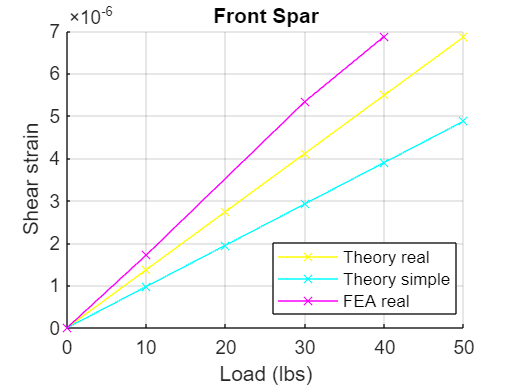

% Plot loading vs shear strain comparisons of theory and FEA
%-------------------------------------------------------------
% % Leading edge
% figure; hold on
% plot(targetLoad(loading_idx),theory_O.real.gamma_leadingEdge(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'Theory real')
% plot(targetLoad(loading_idx),theory_O.simple.gamma_leadingEdge(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'Theory simple')
% %plot(FEA.real.loads,FEA.real.gamma_leadingEdge(loading_idx),Marker = "x", Color = ex_load, DisplayName= 'FEA real')
% % plot(FEA.simple.loads,FEA.real.gamma_leadingEdge(loading_idx),Marker = "x", Color = ex_load, DisplayName= 'FEA real')
% grid on;
% legend
% xlabel('Load (lbs)'); ylabel('Shear strain')
% title('Leading Edge')

% Front Spar
figure; hold on
plot(targetLoad(loading_idx),theory_O.real.gamma_frontSpar(loading_idx), Color = theo_re, LineStyle = load_s,Marker = "x", DisplayName= 'Theory real')
plot(targetLoad(loading_idx),theory_O.simple.gamma_frontSpar(loading_idx), Color = theo_sim, LineStyle = load_s,Marker = "x", DisplayName= 'Theory simple')
plot(FEA.real.loads,FEA.real.gamma_frontSpar, Color = fea_re,Marker = "x", DisplayName= 'FEA real')
% plot(FEA.simple.loads,FEA.real.gamma_frontSpar(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'FEA real')
grid on;
legend('Location','Best')
xlabel('Load (lbs)'); ylabel('Shear strain')
title('Front Spar')

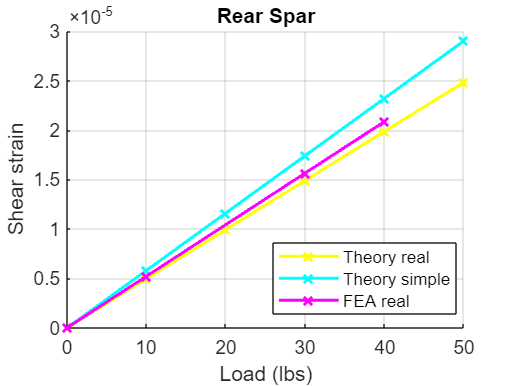


% Rear Spar
figure; hold on
plot(targetLoad(loading_idx),theory_O.real.gamma_rearSpar(loading_idx), Color = theo_re,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'Theory real')
plot(targetLoad(loading_idx),theory_O.simple.gamma_rearSpar(loading_idx), Color = theo_sim,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'Theory simple')
plot(FEA.real.loads,FEA.real.gamma_rearSpar, Color = fea_re,Marker = "x", LineStyle = load_s,LineWidth = line_w, DisplayName= 'FEA real')
% plot(FEA.simple.loads,FEA.real.gamma_rearSpar(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'FEA real')
grid on;
legend('Location','Best')
xlabel('Load (lbs)'); ylabel('Shear strain')
title('Rear Spar')

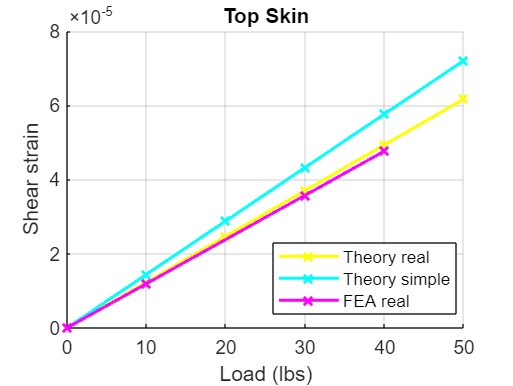


% Top skin
figure; hold on
plot(targetLoad(loading_idx),theory_O.real.gamma_skinTop(loading_idx), Color = theo_re,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'Theory real')
plot(targetLoad(loading_idx),theory_O.simple.gamma_skinTop(loading_idx), Color = theo_sim,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'Theory simple')
plot(FEA.real.loads,FEA.real.gamma_skinTop, Color = fea_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'FEA real')
% plot(FEA.simple.loads,FEA.real.gamma_skinTop(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'FEA real')
grid on;
legend('Location','Best')
xlabel('Load (lbs)'); ylabel('Shear strain')
title('Top Skin')


% Bottom Skin
% figure; hold on
% plot(targetLoad(loading_idx),theory_O.real.gamma_skinBottom(loading_idx), Color = theo_re,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'Theory real')
% plot(targetLoad(loading_idx),theory_O.simple.gamma_skinBottom(loading_idx),LineWidth = line_w, Color = theo_sim, LineStyle = load_s,Marker = "x", DisplayName= 'Theory simple')
% plot(FEA.real.loads,FEA.real.gamma_skinBottom, Color = fea_re,LineWidth = line_w, LineStyle = load_s,Marker = "x", DisplayName= 'FEA real')
% % plot(FEA.simple.loads,FEA.real.gamma_skinBottom(loading_idx), Color = ex_load,Marker = "x", DisplayName= 'FEA real')
% grid on;
% legend('Location','Best')
% xlabel('Load (lbs)'); ylabel('Shear strain')
% title('Bottom Skin')

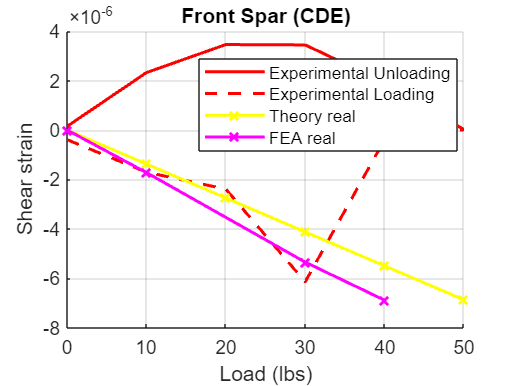

% Plot torque vs shear strain for the loading case of experimental, theory(real)
% and FEA(real)

% % Rear Spar
% figure; hold on
% plot(targetLoad(unloading_idx),exp_data.strain_difference_CDE(unloading_idx), DisplayName= 'Experimental Unloading')
% plot(targetLoad(loading_idx),exp_data.strain_difference_CDE(loading_idx), DisplayName= 'Experimental Loading')
% plot(targetLoad,theory_O.real.gamma_rearSpar,Marker = "x", DisplayName= 'Theory real')
% %plot(FEA.real.load,FEA.real.gamma_rearSpar(loading_idx),Marker = "x", DisplayName= 'FEA real')
% grid on;
% xlabel('Load (lbs)'); ylabel('Shear strain')
% title('Rear Spar (CDE)')

% Front Spar
figure; hold on
plot(targetLoad(unloading_idx),-exp_data.strain_difference_CDE(unloading_idx), Color = cde_ex,LineWidth = line_w, LineStyle = load_s, DisplayName= 'Experimental Unloading')
plot(targetLoad(loading_idx),-exp_data.strain_difference_CDE(loading_idx), Color = cde_ex,LineWidth = line_w, LineStyle = unload_s, DisplayName= 'Experimental Loading')
plot(targetLoad,-theory_O.real.gamma_frontSpar, Color = theo_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'Theory real')
plot(FEA.real.loads,-FEA.real.gamma_frontSpar, Color = fea_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'FEA real')
grid on;
legend('Location','Best')
xlabel('Load (lbs)'); ylabel('Shear strain')
title('Front Spar (CDE)')

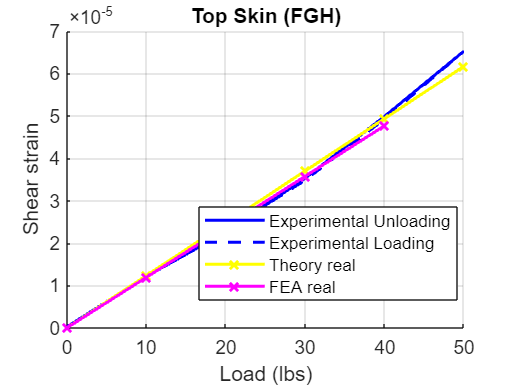


% Top Skin
figure; hold on
plot(targetLoad(unloading_idx),exp_data.strain_difference_FGH(unloading_idx), Color = fgh_ex,LineWidth = line_w, LineStyle = load_s, DisplayName= 'Experimental Unloading')
plot(targetLoad(loading_idx),exp_data.strain_difference_FGH(loading_idx), Color = fgh_ex,LineWidth = line_w, LineStyle = unload_s, DisplayName= 'Experimental Loading')
plot(targetLoad,theory_O.real.gamma_skinTop, Color = theo_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'Theory real')
plot(FEA.real.loads,FEA.real.gamma_skinTop, Color = fea_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'FEA real')
grid on;
legend('Location','Best')
xlabel('Load (lbs)'); ylabel('Shear strain')
title('Top Skin (FGH)')


% Bottom Skin
% figure; hold on
% plot(targetLoad(unloading_idx),exp_data.strain_difference_IJK(unloading_idx), Color = ijk_ex, LineStyle = load_s,LineWidth = line_w, DisplayName= 'Experimental Unloading')
% plot(targetLoad(loading_idx),exp_data.strain_difference_IJK(loading_idx), Color = ijk_ex, LineStyle = unload_s,LineWidth = line_w, DisplayName= 'Experimental Loading')
% plot(targetLoad,theory_O.real.gamma_skinBottom, Color = theo_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'Theory real')
% plot(FEA.real.loads,FEA.real.gamma_skinBottom, Color = fea_re, LineStyle = load_s,LineWidth = line_w,Marker = "x", DisplayName= 'FEA real')
% grid on;
% legend('Location','Best')
% xlabel('Load (lbs)'); ylabel('Shear strain')
% title('Bottom Skin (IJK)')